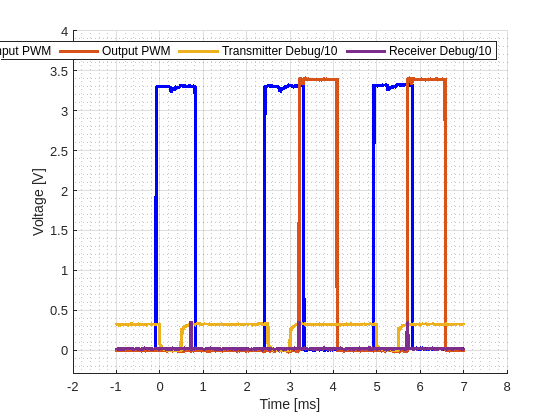

% Clearing
close all; clear all; clc; clf;

% Load the mat file
load receiver_new.mat

% Creating time array
time = Tstart + (0:length(A)-1)*Tinterval;

%Convert in ms
time= time.*10^+3;

% Changing time array
Tstart_new= -0.001;
n = ceil((Tstart_new - Tstart)/Tinterval);
time = time(n:end);

% Smoothing jagged oscilloscope signal with moving average filter
thrDebugHigh = 0.2;
thrDebugLow = 0.08;

thrPWMhigh = 3;
thrPWMlow = 0.08;

windowSize = 10;

BhighDebugIndx = find(B>thrDebugHigh);
ChighDebugIndx = find(C>thrDebugHigh);
AhighPWMIndx = find(A>thrPWMhigh);
DhighPWMIndx = find(D>thrPWMhigh);

BlowDebugIndx = find(B<thrDebugLow);
ClowDebugIndx = find(C<thrDebugLow);
AlowPWMIndx = find(A<thrDebugLow);
DlowPWMIndx = find(D<thrDebugLow);


Asmooth = A;
Bsmooth = B;
Csmooth = C;
Dsmooth = D;


Asmooth(AhighPWMIndx) = movmean(A(AhighPWMIndx), windowSize);
Bsmooth(BhighDebugIndx) = movmean(B(BhighDebugIndx), windowSize);
Csmooth(ChighDebugIndx) = movmean(C(ChighDebugIndx), windowSize);
Dsmooth(DhighPWMIndx) = movmean(D(DhighPWMIndx), windowSize);

Asmooth(AlowPWMIndx) = movmean(A(AlowPWMIndx), windowSize);
Bsmooth(BlowDebugIndx) = movmean(B(BlowDebugIndx), windowSize);
Csmooth(ClowDebugIndx) = movmean(C(ClowDebugIndx), windowSize);
Dsmooth(DlowPWMIndx) = movmean(D(DlowPWMIndx), windowSize);

% Plot
figure('Name','Delay');
hold on;
plot(time, Asmooth(n:end), 'Color', "blue", 'DisplayName','Input PWM', 'LineWidth',2.5);
plot(time, Dsmooth(n:end), 'Color', "#D95319", 'DisplayName','Output PWM','LineWidth',2.5);
plot(time, Bsmooth(n:end), 'Color', "#EDB120", 'DisplayName','Transmitter Debug/10','LineWidth',2.5);
plot(time, Csmooth(n:end), 'Color', "#7E2F8E", 'DisplayName','Receiver Debug/10','LineWidth',2.5);
hold on;
grid on;
grid minor;
xlabel('Time [ms]');
ylabel('Voltage [V]');
ylim([-0.3, 4])
legend('Location','north','NumColumns',4)